# **A gentle introduction to linear systems**

Mahdi Khoramshahi

## **Linear models**

In the first lecture, we focus on linear systems which can be written in matrix form:


$$y = A(x) p$$


where $x\in R^{n_x }$,$p\in R^{n_p }$, $y\in R^{n_y \;}$and $A\in R^{n_{y\;} \times n_p }$.

Here is an example with 4 inputs ($n_x =4$) and 2 output ($n_y =2$) while there are 2 parameters ($n_p =2$):


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
x_1  & -x_2 \\
-x_1  & x_3 x_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_1 \\
p_2 
\end{array}\right\rbrack$$


This model is impelemented in Matlab function in the same directory: "model_example_1.m". We can call this function to obtain measurements, but we are not supposed to look inside and check what are the "ture" parameters being used.

Let's measure the system output at the following input:

x_1 = [1 ; 1 ; 1 ; 1];
y_1 = model_example_1(x_1)

y_1 =      0
     0


Let's do another measurement:

x_2 = [1 ; 0 ; 1 ; 0];
y_2 = model_example_1(x_2)

y_2 =     0.5000
   -0.5000


## Regrouping (concatenation) of the data

As presented in the couse, we would like to concatenate the data and represent them as follows:


$$Y = \Phi(X) p$$


where $X\in R^{Nn_x }$,$Y\in R^{Nn_y }$, $\Phi \;\in R^{Nn_y \times n_p }$.

Let's concatenate the two meausres in the previous example.

For this we need to use our model. We use an anonymous function:

A = @(x) [x(1) -x(2); -x(1) x(3)*x(4)];

Notice that here, we are exploiting the fact that we know the model (but not the parameters)!

***Careful! from now on 'A' is a fucntion.

Now, we can plug in $x_1$and $x_2$:

Phi = [A(x_1) ; A(x_2)]

Phi =      1    -1
    -1     1
     1     0
    -1     0


Similarly for $Y$:

Y = [y_1 ; y_2]

Y =          0
         0
    0.5000
   -0.5000


Using the these two matrices, we can estimate the parameters using least-square method:

p_hat = inv(Phi'*Phi)*Phi'*Y

p_hat =     0.5000
    0.5000


We will explain further this equation later. For now let's see how we can generate many datapoints using our simulated model:

N = 10;   % you can change the number of measurements
sigma = 0; % with this, we add noise to our measurement (y)

Phi = []; % we start with empty matrices
Y = [];

for n = 1:N
    x = randn(1,4);  % a random input
    Phi = [Phi ; A(x)];
    Y = [Y ; model_example_1(x)+sigma*randn(2,1)];

end

We can see how the size of $\Phi \;$and $Y$ changes as we change the number of measurements ($N$): 

size(Phi)

ans =     20     2


size(Y)

ans =     20     1


Finally, our estimation of the parameters:

p_hat = inv(Phi'*Phi)*Phi'*Y

p_hat =     0.5000
    0.5000


We can go back and introduce noise to the measurements (Guassian noise with variance $\sigma \;$) and see how the the estimated parameters are affected. Moreover, we can see having higher number of measurements ($N$) can help reduce the effect of the noise.

## Special case: Square matrix

Indeed if there is no noise, having $n_{p\;}$observation is enought to estimate $n_{p\;}$parameters: i.e, $\Phi \;\in R^{n_p \times n_p }$ is a square matrix.

In this case, to solve:


$$Y = \Phi(X) p$$


we can use the matrix inversion :


$$\hat{p} = (\Phi(X))^{-1} p$$


where we take the inverse of $\Phi$.

Let's try to find the parameter of the same model, using matrix inversion.

x_first_try = [1 ; 1 ; 1 ; 1];
Phi_first_try = [A(x_first_try)];
y_first_try = model_example_1(x_first_try);
p_hat = inv(Phi_first_try)*y_first_try

p_hat =    NaN
   NaN


We were not lucky and we got NaN! Obviously $\Phi$ is not invertible. 

A better practice is to check the matrix before taking the inversion. There a several ways to check if the matrix is invertible:

1) if all eigen values are nonzero:

eig(Phi_first_try)

ans =      0
     2


2) if the rank of the matrix smaller than the size of the matrix (row or column)

rank(Phi_first_try) , length(Phi_first_try)

ans = 1

ans = 2

3) if the smallest singular value is nonzero

min(svd(Phi_first_try))

ans = 3.3547e-17

4) Numerically, if the condition number is NOT too high

cond(Phi_first_try)

ans = 5.9618e+16

Let's pretend to be lucky and pick another input:

x_lucky = [1 ; 0 ; 1 ; 1];
Phi_lucky = [A(x_lucky)];
y_lucky = model_example_1(x_lucky);
p_hat = inv(Phi_lucky)*y_lucky

p_hat =     0.5000
    0.5000


So, it worked since the $\Phi$ was inversible:

rank(Phi_lucky) , cond(Phi_lucky)

ans = 2

ans = 2.6180

However, in practical cases, we collected as much as data that we can and we use the least-square method since the $\Phi$ would have a better condition number. 

In the following code, we can see tha we always risk of having relatively high condition number when we rely on one or two measurements.

*** play around witht the slider:

N = 5;   % you can change the number of measurements

Phi = []; % we start with empty matrices

for n = 1:N
    x = randn(1,4);  % a random input
    Phi = [Phi ; A(x)];
end

cond(Phi)

ans = 1.5314

## Least square method

### A simple example

Let's start with a simple case of line fitting. We want to fit a line with 2 parameters (the slope and the intercept) using three datapoints.

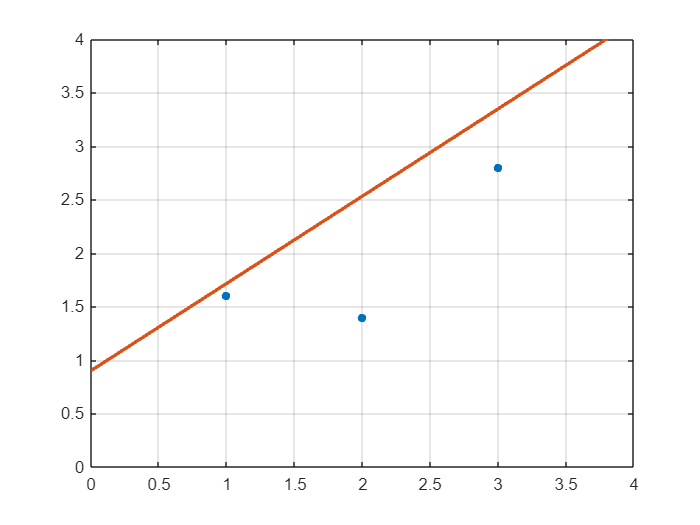

slope = 0.816;
intercept = 0.9;
t=0:0.5:4;
y_line = slope.*t+intercept;
figure;
x = [1; 2; 3];
y = [1.6;1.4; 2.8];
plot(x,y,'Marker','.','MarkerSize',15,'LineStyle','none'); hold on
grid on; xlim([0 4]); ylim([0 4]);
plot(t,y_line,'LineWidth',2)

The error (sum of squares) for the line is:

y_estimated = x .* slope + intercept;
error_manual = sum((y-y_estimated).^2)

error_manual = 1.5952

It is obvious to see we can never get zero error since there is not line that can pass through them all. However, the idea is to minimize this error.

First we need to write the model in the matrix form:


$$y = p_1 x + p_2$$


where $p_{1\;}$is the slope and $p_2$ is the intercept. Therefore:


$$y=\left\lbrack \begin{array}{cc}
x & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_1 \\
p_2 
\end{array}\right\rbrack$$


So, we can write the A as a matlab anonymous function: 

A_line = @(x) [x 1];

Let regroup our datapoints:

Phi_line = [A_line(x(1)) ; A_line(x(2)) ; A_line(x(3))]

Phi_line =      1     1
     2     1
     3     1


Y_line = y

Y_line =     1.6000
    1.4000
    2.8000


Before using matrix inversion, we should check if the condition number is low enough.

cond(Phi_line)

ans = 6.7930

p_hat = inv(Phi_line'*Phi_line)*Phi_line'*Y_line

p_hat =     0.6000
    0.7333


we can compute the error associated with this estimation:

Y_hat = Phi_line * p_hat;
error_least_square = sum((Y_line-Y_hat).^2)

error_least_square = 0.4267

If you don't beleive in math, you can try to get a lower error than this by playing around with slope and intercept sliders!

### Noisy measurements

Let us repeat the same line-fitting problem but this time including noise and higher number of points. We assume the datapoints are coming from this process:


$$y=\textrm{Ax}+\epsilon$$


where $\epsilon$ is the measurement noise which follows a IID normal distribution. 

Let's assume the true parameters as follows:

p_star = [1 0];

which means slope of one and intercept of zero. A simple choice for better illustration purposes!

So let's make measurements.

N = 50;
sigma = 0.5;
x = rand(N,1)*4; % uniform distribution between 0 and 4
y = x.*p_star(1) + p_star(2) + sigma * randn(N,1);

Like before, we need to form $\Phi$ and $Y$.

Phi = []; % we start with empty matrices
Y = [];

for n = 1:N
    Phi = [Phi ; A_line(x(n))];
end

Y = y;


Before computing the pseudo-inverse, let us look at the condition number:

cond(Phi)

ans = 4.7371

Our estimated parameters are:

p_hat = inv(Phi'*Phi)*Phi'*Y

p_hat =     1.0028
    0.0733


Let's plot the datapoints and estimated line:

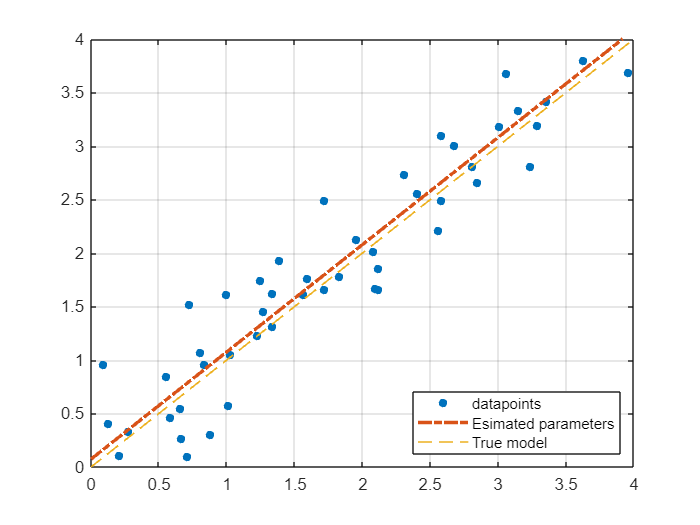

t=0:0.1:4;
y_line_true = p_star(1).*t+p_star(2);
y_line_esimated = p_hat(1).*t+p_hat(2);

figure;
plot(x,y,'Marker','.','MarkerSize',15,'LineStyle','none'); hold on
grid on; xlim([0 4]); ylim([0 4]);
plot(t,y_line_esimated,'-.','LineWidth',2)
plot(t,y_line_true,'--','LineWidth',1)
legend('datapoints','Esimated parameters','True model','Location','southeast')

The standard error is:

error_std = sqrt(sum((Y - Phi*p_hat).^2)/N)

error_std = 0.3704

You can go back and play around the the number of observations and the variance of the noise; for example, crank up both!

## A Practial way to solve Ax = b in Matlab

Let's take vales from our last example:

Phi, Y

Phi =     1.2262    1.0000
    2.8457    1.0000
    1.3369    1.0000
    0.8832    1.0000
    0.6701    1.0000
    2.4082    1.0000
    3.0067    1.0000
    3.0643    1.0000
    0.5832    1.0000
    1.0301    1.0000


Y =     1.2314
    2.6568
    1.3155
    0.3033
    0.2645
    2.5582
    3.1785
    3.6801
    0.4602
    1.0544


Indeed, we can use the pseudo inverse method:

p_hat_method_1 = inv(Phi'*Phi)*Phi'*Y

p_hat_method_1 =     1.0028
    0.0733


We can use the "pinv()" function to compute the pseudo-inverse:

p_hat_method_2 = pinv(Phi)*Y

p_hat_method_2 =     1.0028
    0.0733


However, matlab proposes a fast and efficent way to solve Ax = b equation using "\" :

p_hat_method_3 = Phi\Y

p_hat_method_3 =     1.0028
    0.0733


It is not only shorter to code, but also faster. Matlab take a shortcut to solve the problem without explicity solving for the pseudo-inverse.

## Some remarks on Singular Value Decomposition

In Matlab, we can compute SVD of a matrix as follows:

B = randn(4,2);
[U,S,V] = svd(B)   % B = U*S*V'

U =     0.6944    0.4523   -0.2816   -0.4836
   -0.3936   -0.3395   -0.0516   -0.8527
    0.0763    0.2603    0.9424   -0.1959
   -0.5975    0.7825   -0.1731   -0.0253


S =     2.0253         0
         0    1.0785
         0         0
         0         0


V =     0.3497    0.9369
   -0.9369    0.3497


An important property: U and V are unitary matrices:

V*V'

ans =     1.0000         0
         0    1.0000


U'*U

ans =     1.0000   -0.0000    0.0000    0.0000
   -0.0000    1.0000    0.0000   -0.0000
    0.0000    0.0000    1.0000   -0.0000
    0.0000   -0.0000   -0.0000    1.0000


This makes eay to construct an left-pseudo inverse.

First, we need to inverse the singular values:

S_inv = S';
S_inv(1,1) = 1./S_inv(1,1);
S_inv(2,2) = 1./S_inv(2,2)

S_inv =     0.4938         0         0         0
         0    0.9272         0         0


and then:

B_pinv = V*S_inv*U'

B_pinv =     0.5128   -0.3629    0.2393    0.5766
   -0.1746    0.0720    0.0491    0.5301


B_pinv * B

ans =     1.0000    0.0000
    0.0000    1.0000


This works because:


$$B^+ B=\left({\textrm{VS}}^+ U^T \right)\left({\textrm{USV}}^T \right)={\textrm{VS}}^+ {\textrm{SV}}^T ={\textrm{VV}}^T =I$$


It is important to note that it is the singular values that are being inversed! so it would be dangerous that smallest singular values is too small (close to zero), or the biggest one is too big. That's why it is always a good practice to look the condition number of the matrix (i.e., the ration between the biggest and smallest singular value).

The End.